# 姿勢とライトカーブをplot

- "慣性モーメント固定，形状は違う"

という条件において，どれだけ姿勢とライトカーブが変わるか．を確認したい

freeMotionも黒でplot

clc
clear
close all

curdir = pwd;
addpath(strcat(curdir, '/../../hara_functions'));

shapes = ["freeMotion", "boxWing", "boxOneWing", "box"];

for j = 1:1:size(shapes, 2)

### read data

    % read train data ---------------------------------------------------------
    % [t_, mApp, q1, q2, q3, q4, w1, w2, w3], shape=(tspan, 9)
    cddir = strcat('../../data/traindata/', shapes(1,j), '/'); 
    cd(cddir)
    trainStruct = dir('*.csv'); % 構造体にtraindata fileを格納
    fName = trainStruct(1).name; df = readmatrix(fName); % for acquiring the size of a file
    trainDF = zeros(size(df, 1), size(df, 2), size(trainStruct, 1)); % 事前割り当て, shape=(tspan, 9, valid fileの数)
    for i = 1:1:size(trainStruct, 1)
        fName = trainStruct(i).name;
        df = readmatrix(fName);
        trainDF(:, :, i) = df;
    end
    
    % read valid data ----------------------------------------------------------
    cddir = strcat('../../validdata/', shapes(1, j), '/');
    cd(cddir);
    validStruct = dir('*.csv'); % Structureにvaliddata fileを格納
    fName = validStruct(1).name; df = readmatrix(fName); % for acquiring the size of a file
    validDF = zeros(size(df, 1), size(df, 2), size(validStruct, 1)); % 事前割り当て, shape=(tspan, 9, valid fileの数)
    for i = 1:1:size(validStruct, 1)
        fName = validStruct(i).name;
        df = readmatrix(fName);
        validDF(:, :, i) = df;
    end
    
    cd '../../../create_traindata/hara_codes/';

### data handling

    if j == 1
        freeMotionDF = trainDF;
        freeMotionDF_valid = validDF;
    elseif j == 2
        boxWingDF = trainDF;
        boxWingDF_valid = validDF;
    elseif j == 3
        boxOneWingDF = trainDF;
        boxOneWingDF_valid = validDF;
    elseif j == 4
        boxDF = trainDF;
        boxDF_valid = validDF;
    end
end

### plot

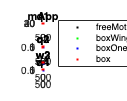

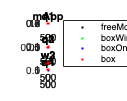

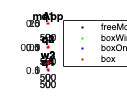

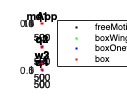

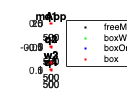

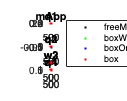

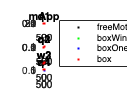

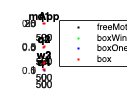

fignames = ["mApp", "q1", "q2", "q3", "q4", "w1", "w2", "w3"];
x_label = "time [s]";
y_labels = ["magnitude", "q1", "q2", "q3", "q4", "\omega_1 [deg/s]", "\omega_2 [deg/s]", "\omega_3 [deg/s]"];

t = boxWingDF(:, 1, 1);
N = size(boxWingDF, 3);
% N = 3 
for j = 1:1:N
    figure('Name', num2str(j), 'Position', [200, 20, 1000, 800]);
    tcl = tiledlayout(4, 2);
    for i = 1:1:size(fignames, 2)
        nexttile(tcl);
        if i == 1
            plot_various_shapes(t, freeMotionDF(:, i+1, j), boxWingDF(:, i+1, j), boxOneWingDF(:, i+1, j), boxDF(:, i+1, j), fignames(i), x_label, y_labels(i)); % mAppをplot
        else
            plot_various_shapes(t, freeMotionDF(:, i+7, j), boxWingDF(:, i+7, j), boxOneWingDF(:, i+7, j), boxDF(:, i+7, j), fignames(i), x_label, y_labels(i)); % 軌道位置（r, v）が入ってるから
        end
    end
    lgd = legend({"freeMotion", "boxWing", "boxOnewing", "box"});
    lgd.Layout.Tile = 'East';
end

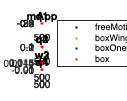

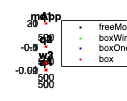

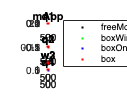


N_valid = size(boxDF_valid, 3);
for j = 1:1:N_valid
    figure('Name', strcat(num2str(j), "_valid"), 'Position', [200, 20, 1000, 800]);
    tcl = tiledlayout(4, 2);
    for i = 1:1:size(fignames, 2)
        nexttile(tcl);
        if i == 1
            plot_various_shapes(t, freeMotionDF_valid(:, i+1, j), boxWingDF_valid(:, i+1, j), boxOneWingDF_valid(:, i+1, j), boxDF_valid(:, i+1, j), fignames(i), x_label, y_labels(i)); % mAppをplot
        else
            plot_various_shapes(t, freeMotionDF_valid(:, i+7, j), boxWingDF_valid(:, i+7, j), boxOneWingDF_valid(:, i+7, j), boxDF_valid(:, i+7, j), fignames(i), x_label, y_labels(i)); % 軌道位置（r, v）が入ってるから
        end
    end
    lgd = legend({"freeMotion", "boxWing", "boxOnewing", "box"});
    lgd.Layout.Tile = 'East';
end

function plot_various_shapes(x, y1, y2, y3, y4, figname, x_label, y_label)
arguments
    x (:, 1) {mustBeNumeric}
    y1 (:, 1) {mustBeNumeric}
    y2 (:, 1) {mustBeNumeric}
    y3 (:, 1) {mustBeNumeric}
    y4 (:, 1) {mustBeNumeric}
    figname {mustBeTextScalar}
    x_label {mustBeTextScalar}
    y_label {mustBeTextScalar}
end
    plot(x, y1, 'k.'); % freeMotion
    hold on;
    plot(x, y2, 'g.'); % boxWing
    hold on;
    plot(x, y3, 'b.'); % boxOneWing
    hold on;
    plot(x, y4, 'r.') % box
    hold off;
    

    title(figname);
    % legend({"boxWing", "boxOnewing", "box"});
    xlabel(x_label);
    ylabel(y_label);
end